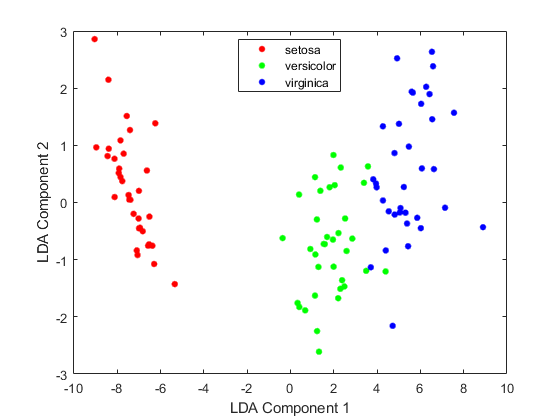

clc
clear
% Step 1: Load the fisheriris dataset
load fisheriris

% Step 2: Extract the feature matrix X and class labels y
means = mean(meas);
devs = std(meas);
for i = 1:size(meas,2)
    X(:,i) = (meas(:,i)-means(i))/(devs(i));
end
% X = meas; % Feature matrix (150 samples x 4 features)
y = species; % Class labels (setosa, versicolor, virginica)

% Step 3: Split the data into training and testing sets
rng('default'); % For reproducibility
cv = cvpartition(y, 'Holdout', 0.3); % 70% training, 30% testing
X_train = X(training(cv), :);
y_train = y(training(cv));
X_test = X(test(cv), :);
y_test = y(test(cv));

% Step 4: Apply LDA for dimensionality reduction on the training data
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X_train, y_train); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Step 5: Project training and testing data onto the LDA components
X_train_reduced = X_train * projection_matrix;
X_test_reduced = X_test * projection_matrix;

lda_reduced = fitcdiscr(X_train_reduced, y_train);
% Step 6: Visualization of training data in the reduced dimensional space
gscatter(X_train_reduced(:, 1), X_train_reduced(:, 2), y_train, 'rgb');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

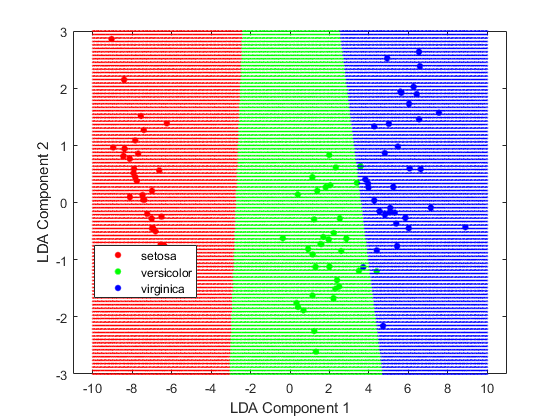


[L, W] = meshgrid(linspace(-10, 10, 500), linspace(-3,3,100)); ...
L = L(:);
W = W(:);
pred = lda_reduced.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
xlabel('LDA Component 1');
ylabel('LDA Component 2');
legend('setosa', 'versicolor', 'virginica', 'Location', 'best');
hold off; 
print('results/LDA_visual_iris', '-dpng', '-r600')

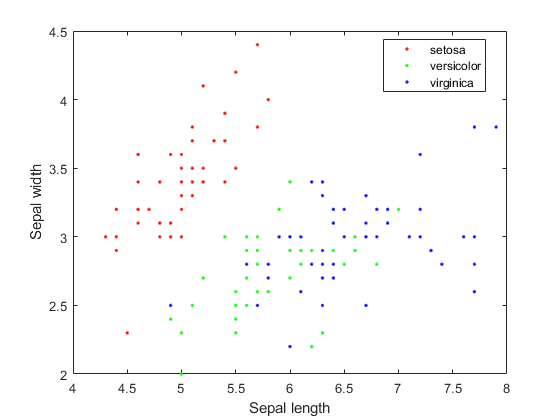

plot(meas(1:50, 1), meas(1:50, 2), '.r', 'LineWidth', 2, 'MarkerSize', 6);
hold on;
plot(meas(51:100, 1), meas(51:100, 2), '.g', 'LineWidth', 2, 'MarkerSize', 6);
plot(meas(101:150, 1), meas(101:150, 2), '.b', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Sepal length');
ylabel('Sepal width');
legend('setosa', 'versicolor', 'virginica', 'Location', 'best');
hold off;

% print('results/fisher_iris_visual', '-dpng', '-r600')


% Step 8: Predict on the test data and calculate the confusion matrix
y_pred = predict(lda_model, X_test);
C = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    15     0     0
     0    15     0
     0     0    15

